# Thermodynamics of N-Schlogl

%specify roots
%fix root to 1
r = sym('r',[1 2])

$$r = \left(\begin{array}{cc} r_{1} & r_{2} \end{array}\right)$$

roots = [ 1 r]

$$roots = \left(\begin{array}{ccc} 1 & r_{1} & r_{2} \end{array}\right)$$

%get rate from roots
poly = -1;
x = sym('x');
for i = 1:size(roots,2)
    poly = poly*(x-roots(i));
end
poly

$$poly = -\left(r_{1}-x\right)\,\left(r_{2}-x\right)\,\left(x-1\right)$$

poly_func = matlabFunction(poly)

poly_func = function_handle with value:
    @(r1,r2,x)-(r1-x).*(r2-x).*(x-1.0)


%Get rate cosntants 
C = coeffs(poly,x)

$$C = \left(\begin{array}{cccc} r_{1}\,r_{2} & -r_{1}-r_{2}-r_{1}\,r_{2} & r_{1}+r_{2}+1 & -1 \end{array}\right)$$

k_const = abs(C)

$$k\_const = \left(\begin{array}{cccc} \left|r_{1}\,r_{2}\right| & \left|r_{1}+r_{2}+r_{1}\,r_{2}\right| & \left|r_{1}+r_{2}+1\right| & 1 \end{array}\right)$$

k_const_fun = matlabFunction(k_const);

%get forward and backward rates
rplus = 0;
rmin = 0;

for i = 1:size(k_const,2)
    if mod(i,2) == 0
        rmin = rmin + k_const(i)*x^(i-1);
    else 
        rplus = rplus + k_const(i)*x^(i-1);
    end
end
rpoly = rplus - rmin;

%verify rate from roots and rate cosntants is the same
simplify(rpoly-poly)

$$ans = \left|r_{1}\,r_{2}\right|-x\,\left|r_{1}+r_{2}+r_{1}\,r_{2}\right|-x^{3}+x^{2}\,\left|r_{1}+r_{2}+1\right|+\left(r_{1}-x\right)\,\left(r_{2}-x\right)\,\left(x-1\right)$$

%LDF
LDF_grad = log(rmin/rplus);
LDF_grad_func = matlabFunction(LDF_grad)

LDF_grad_func = function_handle with value:
    @(r1,r2,x)log((x.*abs(r1+r2+r1.*r2)+x.^3)./(abs(r1.*r2)+x.^2.*abs(r1+r2+1.0)))


LDF = int(LDF_grad,x);
LDF_func = matlabFunction(LDF)

LDF_func = function_handle with value:
    @(r1,r2,x)-x+x.*log((x.*abs(r1+r2+r1.*r2)+x.^3)./(abs(r1.*r2)+x.^2.*abs(r1+r2+1.0)))+atanh(x.*1.0./sqrt(-abs(r1+r2+r1.*r2))).*sqrt(-abs(r1+r2+r1.*r2)).*2.0+(atanh((x.*sqrt(-abs(r1.*r2).*abs(r1+r2+1.0)))./abs(r1.*r2)).*sqrt(-abs(r1.*r2).*abs(r1+r2+1.0)).*2.0)./abs(r1+r2+1.0)


%check
LDF_func(2,3,x)

$$ans = x\,\log\left(\frac{x^{3}+11\,x}{6\,x^{2}+6}\right)-x+2\,\mathrm{atanh}\left(1\,x\,\mathrm{i}\right)\,\mathrm{i}-6.6332\,\mathrm{atanh}\left(0.3015\,x\,\mathrm{i}\right)\,\mathrm{i}$$

rval = [2 4]

rval =      2     4


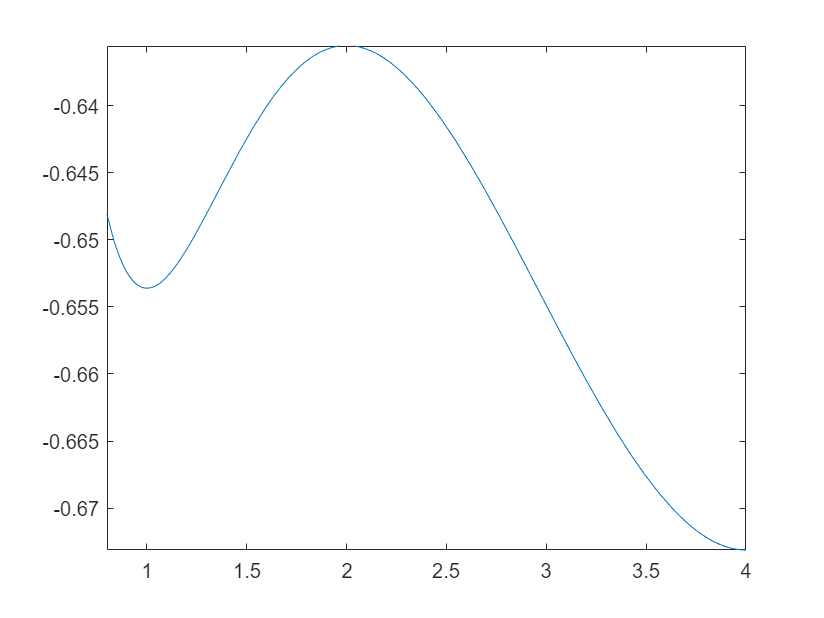

fplot(@(y) real(LDF_func(rval(1),rval(2),y)),[1-0.2,rval(2)])

%make visualization of evolution 
r1_ran = 1.1:0.5:2.1;
r2_ran = 1.1:0.5:4.1;

r1_ran = 0.5:0.2:0.9;
r2_ran = 0.1:0.2:0.9;

[X,Y] = meshgrid(r1_ran,r2_ran);
val_arr = zeros(size(X))

val_arr =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


for i = 1:size(X,1)
    for j = 1:size(X,2)
        if X(i,j)<Y(i,j)
            ratio = (LDF_func(X(i,j),Y(i,j),X(i,j))-LDF_func(X(i,j),Y(i,j),Y(i,j)))/...
(LDF_func(X(i,j),Y(i,j),X(i,j))-LDF_func(X(i,j),Y(i,j),1));
            if ratio > 1
                ratio = 2;
            elseif ratio <1
                ratio = 0.5;              
            end
            val_arr(i,j) = ratio;
        end
    end
end

val_arr

val_arr =          0         0         0
         0         0         0
         0         0         0
    0.5000         0         0
    2.0000    2.0000         0


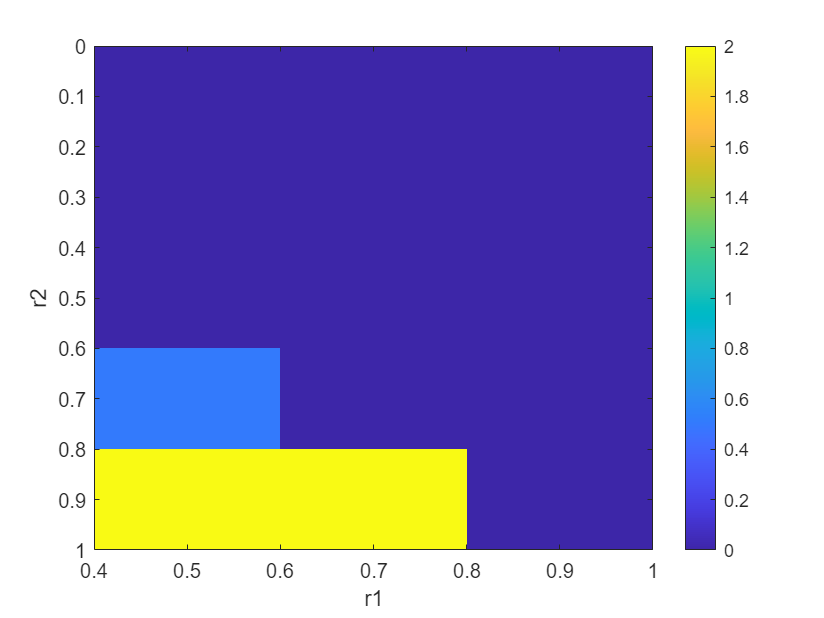

imagesc(r1_ran,r2_ran,val_arr)
colorbar
xlabel('r1')
ylabel('r2')

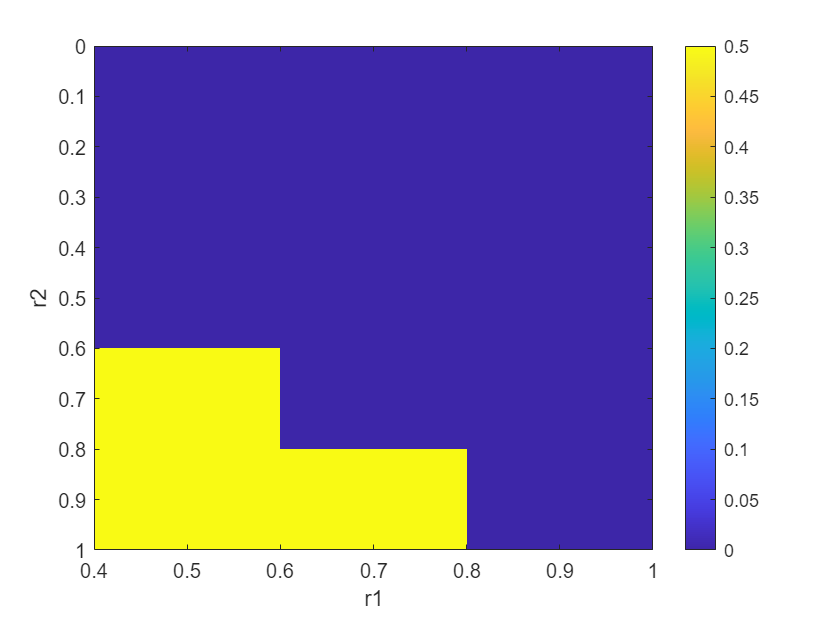

imagesc(r1_ran,r2_ran,trans_arr)
colorbar
xlabel('r1')
ylabel('r2')

%Check transduction along the same parameter choices
trans_arr = zeros(size(X));
for i = 1:size(X,1)
    for j = 1:size(X,2)
        
        if X(i,j)<Y(i,j)
            k_arr = k_const_fun(X(i,j),Y(i,j));
            %ratio of null and AC reaction equilibrium
            [(k_arr(1)/k_arr(2)), (k_arr(3)/k_arr(4))]
            ratio = (k_arr(1)/k_arr(2))/(k_arr(3)/k_arr(4)) 

            if ratio > 1
                %no evolution
                ratio = 2;
            elseif ratio <1
                %evolution - higher attractor favored
                ratio = 0.5;              
            end
            trans_arr(i,j) = ratio;
        end
    end
end

ans =     0.2258    2.2000


ratio = 0.1026

ans =     0.2432    2.4000


ratio = 0.1014

ans =     0.2825    2.6000


ratio = 0.1087

trans_arr

trans_arr =          0         0         0
         0         0         0
         0         0         0
    0.5000         0         0
    0.5000    0.5000         0


%rate across each reaction
r_rxn = [];
%potential change across each reaction
G_rxn = [];

for i = 1:size(k_const,2)/2
     r_rate = k_const(2*i - 1)*x^(2*i-2) -  k_const(2*i)*x^(2*i-1);
    r_rxn = [r_rxn; r_rate];
    G_rxn = [G_rxn; log(rmin/rplus)*r_rate];
end
r_rxn

$$r\_rxn = \left(\begin{array}{c} 6-11\,x\\ 6\,x^{2}-x^{3} \end{array}\right)$$

G_rxn

$$G\_rxn = \left(\begin{array}{c} -\log\left(\frac{x^{3}+11\,x}{6\,x^{2}+6}\right)\,\left(11\,x-6\right)\\ \log\left(\frac{x^{3}+11\,x}{6\,x^{2}+6}\right)\,\left(6\,x^{2}-x^{3}\right) \end{array}\right)$$

r_rxn_func = matlabFunction(r_rxn)

r_rxn_func = function_handle with value:
    @(x)[x.*-1.1e+1+6.0;x.^2.*6.0-x.^3]


G_rxn_func = matlabFunction(G_rxn)

G_rxn_func = function_handle with value:
    @(x)[-log((x.*1.1e+1+x.^3)./(x.^2.*6.0+6.0)).*(x.*1.1e+1-6.0);log((x.*1.1e+1+x.^3)./(x.^2.*6.0+6.0)).*(x.^2.*6.0-x.^3)]


%intrinsic dissipation near equilibrium
diss_eq_1 = log(x/roots(1))*poly;
diss_eq_3 = log(x/roots(3))*poly;
diss_func_1 = matlabFunction(diss_eq_1);
diss_func_3 = matlabFunction(diss_eq_3);

%plots
x_arr = max(0,min(roots)):abs(min(roots))/100: max(abs(roots));

%rate plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,r_rxn_func(x_arr))
end
plot(x_arr,poly_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×3 string array
    "1"    "2"    "total"


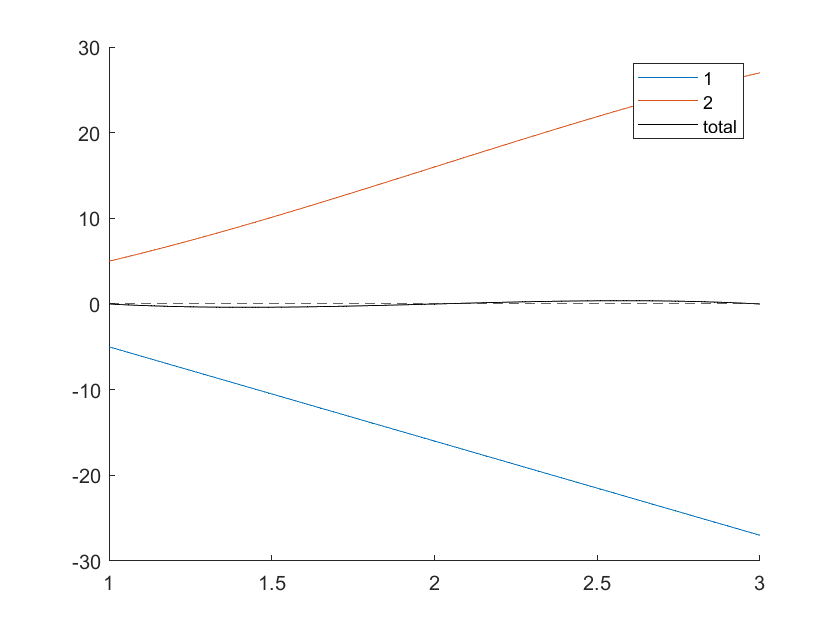

legend(string(label_lst))

%dissipation plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,G_rxn_func(x_arr))
end
plot(x_arr,diss_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×3 string array
    "1"    "2"    "total"


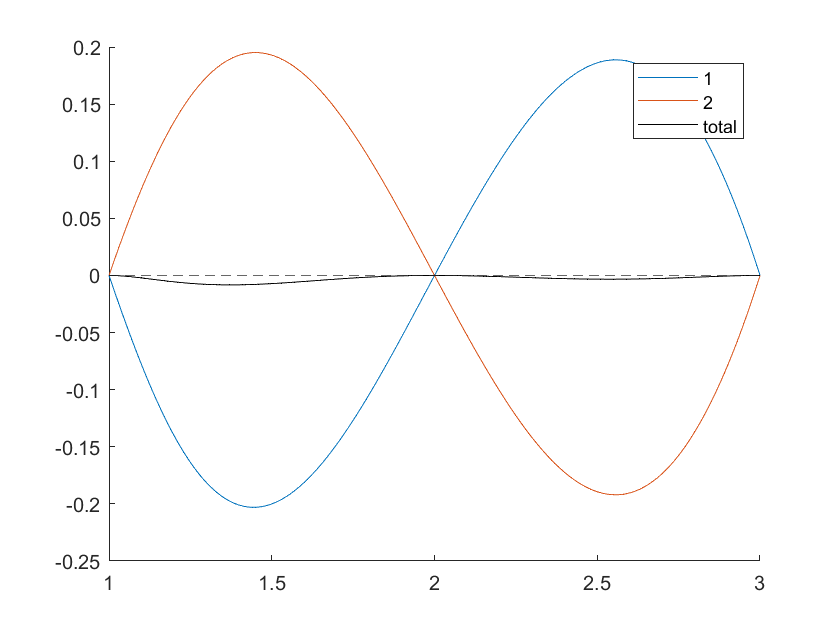

legend(string(label_lst))

%dissipation plots against internal near attractor
figure()
hold on
%label_lst = 1:size(r_rxn,1);
plot(x_arr,diss_func(x_arr),'k')
plot(x_arr,diss_func_1(x_arr),'r')
plot(x_arr,diss_func_3(x_arr),'b')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[ "LDF" "eq1" "eq3"]

label_lst = 1×3 string array
    "LDF"    "eq1"    "eq3"


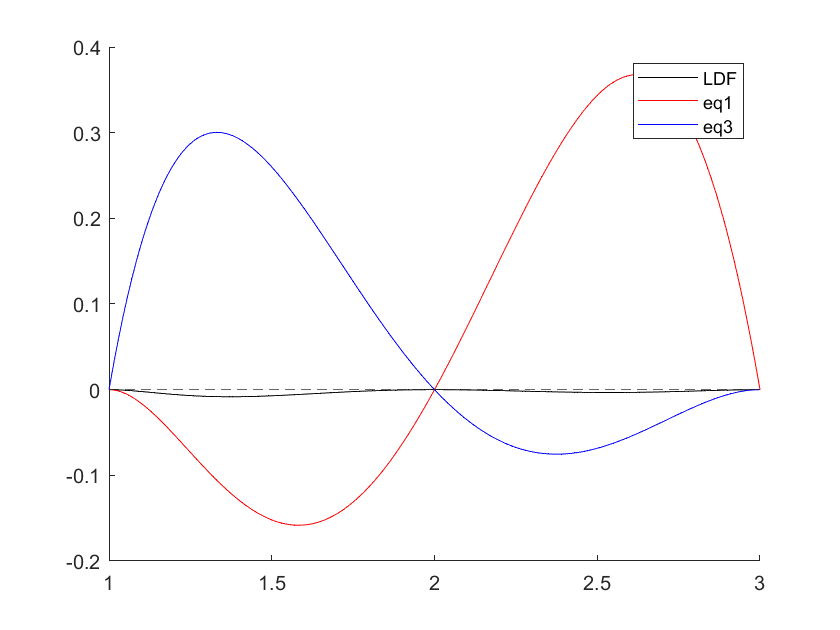

legend(string(label_lst))

label_lst = 1:size(r_rxn,1)

label_lst =      1     2
